**Propotional Controller**

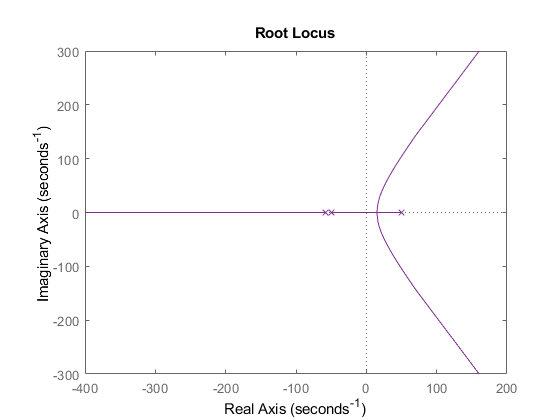

G = zpk([],[-49.5,49.5,-58],60990);
G2 = zpk([],[-49.5,49.5,-58],60990*10);
G3 = zpk([],[-49.5,49.5,-58],60990*100);
G0 = zpk([],[-49.5,49.5,-58],1);
rlocus(G,G2,G3,G0)


%From the above, we can see that adding just propotional gain will not make
%this system stable, hence we have to move towards the lead compensator.

**Lead Compensator**

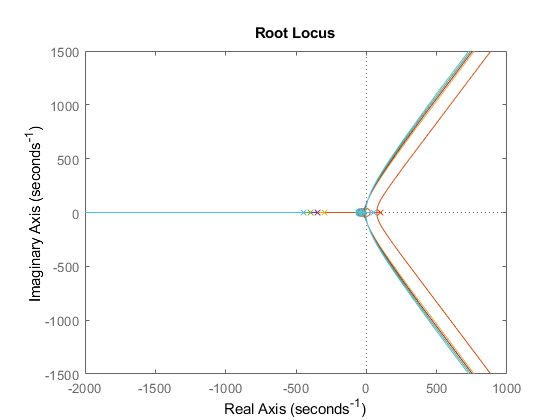

% in the lead compensator, we have the choice to place the zero from 0 to
% -49.5. This means we have infinte possibilities to place the zero. 

% Adding a zero to 0 and to -49.5

G_C = zpk([0],[-49.5,49.5,-58,100],60990);

%Adding a zero at the origin does not make it stable.

G2_C = zpk([-49.5],[-49.5,49.5,-58,-495],60990);

% Adding zeros at: -30,-35,-40,-45

G_C_30 = zpk([-30],[-49.5,49.5,-58,-300],60990);
G_C_35 = zpk([-35],[-49.5,49.5,-58,-350],60990);
G_C_40 = zpk([-40],[-49.5,49.5,-58,-400],60990);
G_C_45 = zpk([-45],[-49.5,49.5,-58,-450],60990);


rlocus(G_C,G_C,G_C_30,G_C_35,G_C_40,G_C_45)

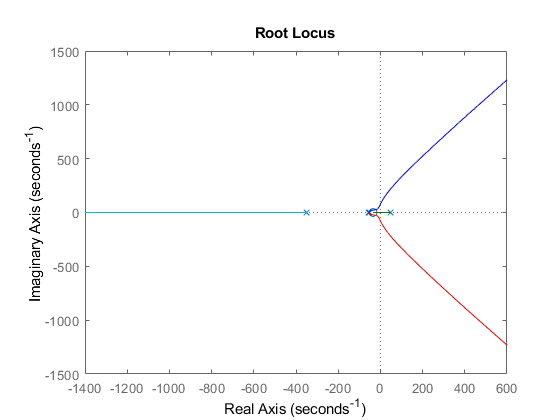


%From the above, we know choose systems where we add a zero at -35.

rlocus(G_C_35)

**Finding Gain**

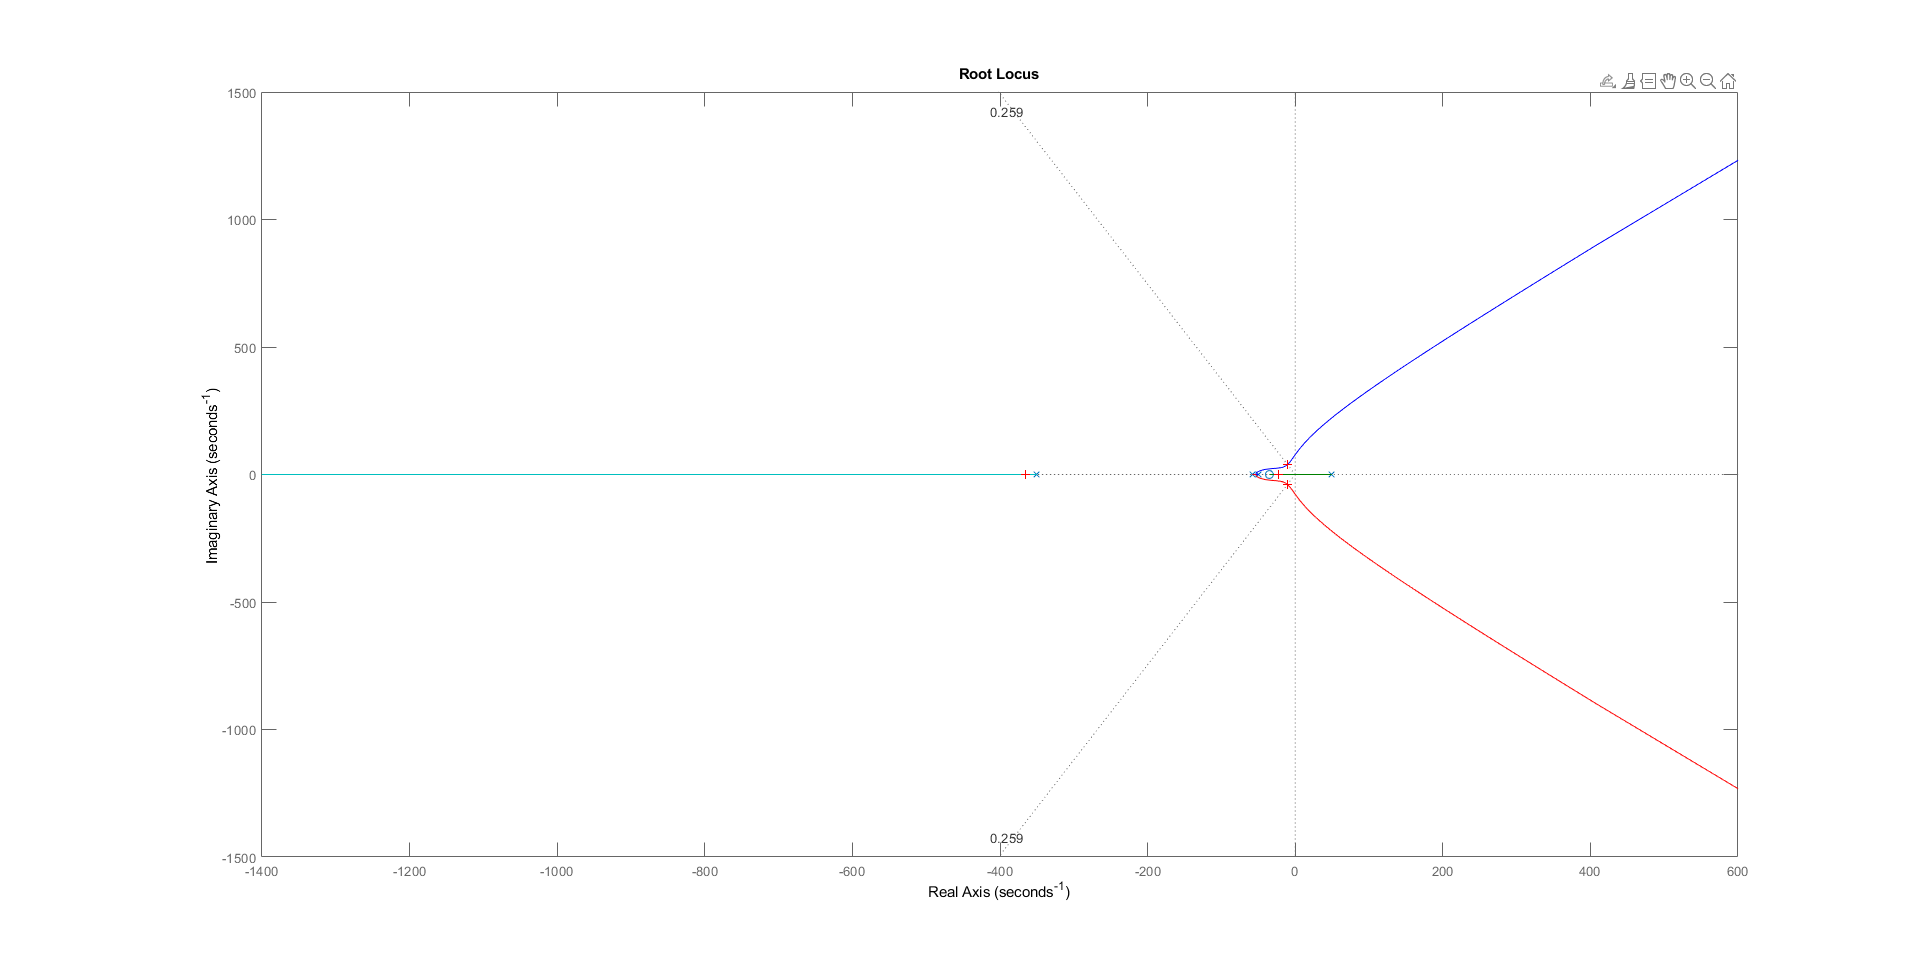

Select a point in the graphics window


selected_point = -10.4336 + 39.2157i

k = 29.6016

p = 	1.0e+02 *

  -3.6485 + 0.0000i
  -0.1035 + 0.3918i
  -0.1035 - 0.3918i
  -0.2244 + 0.0000i


% Now will select our Zeta from taking a range og angles.
% We start wil 50 degrees and we move till 80 degrees.


% Zeta_1 = cosd(50);
% Zeta_2 = cosd(60);
% Zeta_3 = cosd(70);
Zeta_4 = cosd(75);
% Zeta_5 = cosd(80);


sgrid(Zeta_4,0)

[k, p] = rlocfind(G_C_35)

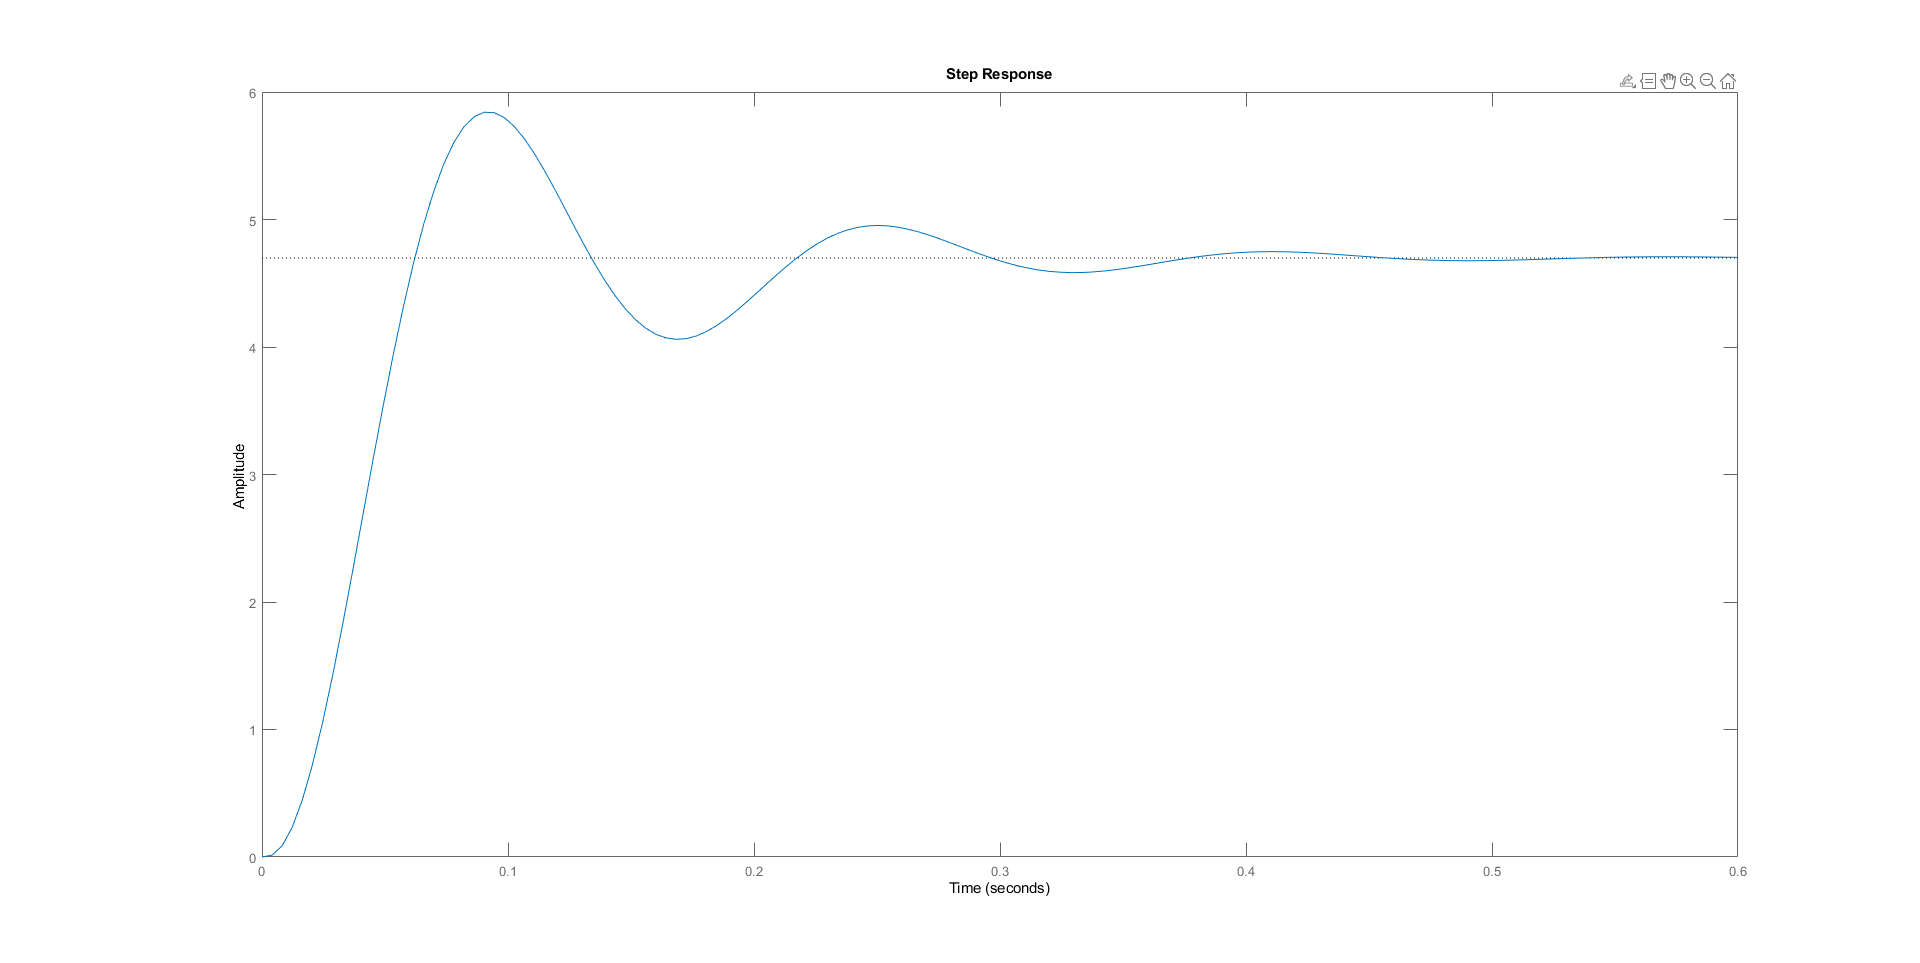


To = feedback(k*G_C_35,1);

step(To)



% After testing all of the zetas on the systems that are at -35 and -40, we
% come to a conclusion that the best results at Theeta = 75, the system wih
% a zero at -35 gives a better result.

% Hence, we are going to use the system with a zero at -35 and Theeta = 75
% The overshoot observed is: 26
% The settling time is: 0.345
% The Value of K is = 29.8

